# Optimal Resource Allocation - An Integer Problem

## Cargo Allocation Process (Bellman, 1962)

Suppose we have a cargo vehicle with which we carry various different types of goods. Each type of good has a specific weight and value per item associated with it. What's in our interest is the best choice of various types of goods to carry at each travel, to obtain the maximum return of operation.

If the goods are possible to divide into as small pieces as needed, then the solution is pretty simple; we simply select whichever type of good has the most value per weight, and fill up the vehicle to its maximum capacity. When indivisible goods are present, however, we can only take integer multiples of these goods, and so the weight distribution is much harder to control or predict without the help of computers. And even though computers are getting more and more powerful with ongoing research and developments, brute forcing the solutions for problems will always have an upper limit of application due to time constraints. 

#### Time Constraints of Direct Comparison

Let's set up an example to see the time constraints that may come up. Assume we have $n
$ types of goods we can put into our cargo vehicle. We would like to see all the possible combinations of allocation of types, given that the sum of the weights of items is less than the maximum capacity of our vehicle. For every maximum capacity we will be able to use a portion of all possible allocations due to the weight limit. For this reason, we will have to construct allocation vectors $(\alpha_1, \alpha_2, ... \, ,a_n) $ (where $\forall i = 1, 2, ... \, , n \, ,\alpha_i \in \{0,1,2,...,\beta_i \}$, $\beta_i = \lfloor \frac{maximum\_capacity}{w_i}\rfloor$ ) that represent how many items of each type has been selected to put in the vehicle. After filtering ones resulting with higher total weight than the maximum capacity of the vehicle, we will compare the total profit from each vector that's viable for the maximum capacity.

- The filtering will be done after the allocation vector is created, creating no significant increase in the order of expected time to finish the calculation.

- Value calculation will be a simple vector product of the vector $values$ with all the vectors that passed from the maximum capacity filter. There will be almost-surely less calculations than all allocation vectors . Again, there is no significant increase in the order of expected time to finish the calculation.

Then the major time consuming activity will be the creation of all possible allocation vectors. For each entry $\alpha_i$, we will choose one number from 0 up to $\beta_i$, resulting in a factor $\binom{\beta_i + 1}{1}$ for all $i=1,2,...\, , n$. Hence, the number of vectors we will have is$\Pi_{i=1}^{n} \binom{\beta_i+1}{1} = \Pi_{i=1}^{n} \;\left(\beta_i+1 \right)$. 

Setting $\beta = \min_i \{ \beta_i \} = \min_i \{ \lfloor \frac{maximum\_capacity}{w_i} \rfloor \} $ we find a lower limit for the number of allocation vectors: 


$$\Pi_{i=1}^{n} \;\left(\beta_i+1 \right) \geq \Pi_{i=1}^{n} \;\left(\beta+1 \right) = (\beta+1)\,^n$$


Hence, a program running this algorithm will need time of order $\mathcal{O}\left( (\beta+1)^n \right)$, which is of unacceptable nature. 

Note: Give a rigorous explanation over "order O(f(n))". 

### Dynamic Programming

Dynamic programming is the technique we apply to such examples, where an optimal allocation of resources is sought after. The main premise this technique requires is instead of allocating the resource at hand at once, we approach the situation in stages. At each stage, an allocation is potentially done, and on the next stage there is less resource to work with. Hence, the problem is converted to an initial stage and later stages problem, to be iterated at every stage. 

#### Principle of Optimality

The saviour we all wait at the first light of the fifth day is the principle of optimality. By the new approach explained above, it is possible to reach an optimal allocation of resources over all of the steps by optimizing the initial step of each stage. The derivation of this is present in Bellman's Applied Dynamic Programming(1962).

We start with presenting given weights and values for each type of good. Below is given the values presented by Bellman (1962, Chapter 1, page 31):

weights = [20; 18; 14; 12; 10; 16; 22; 24];
values = [72; 60; 40; 27; 20; 50; 85; 96];

The order of the entries is very important because values on the same index together represent a type of good.

#### Maximum Capacity

This is the limit for the total weight of goods we put in our carrier. For all weights up to max_capacity the calculations are repeated, because the calculation over the max capacity requires results from lesser capacity cases.

max_capacity = 1000;

#### Value Per Weight Matrix

Each row in this vector has the maximum value from previous row removed. 

-  A matrix that will contain each iteration is created with name $value\_per\_weight\_matrix$

- The first row is attributed the vector that contains all ratios

- The maximum element in row 1 is located. Then the column number is noted. Then the whole column except row 1 is converted to 0.

- Row 2 will not have the maximum element of row 1. So, the previous action is iterated until there is one final element in the final row, which is the type of good with minimum value per weight.

*An additional check might be conducted here; if there are two or more types of goods with same value per weight, only the type of good with the smallest weight per item should stay. The "unique" function, hence, is not really useful here; a different algorithm should be written.

value_per_weight_matrix = zeros(length(weights), length(weights));
% filter out non-unique results wr. to weights

for i = 1:length(weights)
    value_per_weight_matrix(i,:) = values ./ weights;
end
for i = 2:length(weights)
    max_value_per_weight_index = value_per_weight_matrix(i,:) == max(value_per_weight_matrix(i,:));
    column_number = max_value_per_weight_index >= 1;
    value_per_weight_matrix(i:length(weights), column_number) = zeros(1,length(weights)-i+1);
end
disp(value_per_weight_matrix);

    3.6000    3.3333    2.8571    2.2500    2.0000    3.1250    3.8636    4.0000
    3.6000    3.3333    2.8571    2.2500    2.0000    3.1250    3.8636         0
    3.6000    3.3333    2.8571    2.2500    2.0000    3.1250         0         0
         0    3.3333    2.8571    2.2500    2.0000    3.1250         0         0
         0         0    2.8571    2.2500    2.0000    3.1250         0         0
         0         0    2.8571    2.2500    2.0000         0         0         0
         0         0         0    2.2500    2.0000         0         0         0
         0         0         0         0    2.0000         0         0         0



#### Allocation Matrix

We will construct an ND-array to collect what number of each type of good is used. 

The z-index is the number of possible choices for types of goods, the x-index is the capacity filled, and y-index is the type of good that's used. 

For example, if we are looking at "resource_allocation(50,:,3)", it means there will be 3 types of goods that is usable to fill a weight capacity of 50, and each entry in this row vector will show how many of each type of good, from 1 to 8, is used. 

resource_allocation = zeros(max_capacity, length(weights), length(weights));
% the rows are allocations, the columns are types of cargos
% the z-index indicates allocations with that many choices of cargo

### Calculations 

#### Single Type Optimal Choice

We're calculating what's going inside "resource_allocation(:,:,1)", i.e. the resource allocation/choice of cargo for  maximum obtainable value at each row(==capacity from 1 to max_capacity).

At each capacity from 1 to max_capacity, these steps are followed:

- A variable to hold the biggest return is set, starting at zero 

- For each type of good, the maximum value obtainable for that type is calculated, stored inside "value"

- If value is strictly greater than biggest_return, then this value is now the biggest return for this capacity, obtained by the current type

- Resource allocation vector for this capacity is renewed with this specific item type and the number of this item

% usable types = 1
for capacity = 1:max_capacity
    biggest_return = 0;
    for type = 1:length(weights)
        value = values(type)*fix(capacity/weights(type));         
        if value > biggest_return
            biggest_return = value;
            resource_allocation(capacity,:,1) = zeros(1,length(weights));
            resource_allocation(capacity,type,1) = resource_allocation(capacity,type,1) + fix(capacity/weights(type)); 
        end
    end
end

#### Returns of Single Type Optimal Allocations

returns_matrix_single = zeros(max_capacity,1);
for capacity = 1:max_capacity
    returns_matrix_single(capacity) = resource_allocation(capacity,:,1)*values;
end

### Multiple Type Optimal Choice

#### Returns Matrix

Rows are different capacities, and columns are number of types allowed for usage

returns_matrix = zeros(max_capacity, length(weights));
returns_matrix(:, 1)=returns_matrix_single;

#### Multiple Type Optimal Choice

Assume we are trying to fill the second matrix "resource_allocation(:,:,2)" which holds the optimal resource allocations in rows for each capacity with two types of goods used. WLOG assume an arbitrary capacity sufficiently large to use a second type of good. 

- For each value "selection" from 0 to the current assumed capacity, a loop follows as in step 2:

- For each type of item, maximum number of items loadable to the carrier is chosen to be used in step 3:

- After these items are loaded, we can obtain the optimal allocation for the remaining weight from the matrix "resource_allocation(:,:,1)". 

- The maximum value obtained at each selection is stored in the biggest_return, and any allocation surpassing biggest_return is stored back in the resource_allocation(capacity,:,2).

The result we obtained in step 2 leads us to the best allocation for initial stage, and step 3 leads us to the solution of the remaining states. 

In the exact same fashion, matrices "resource_allocation(:,:,3)" to "resource_allocation(:,:,length(weights))" is filled. 

% the z-index of "resource_allocation" is for number of types usable, so
% while filling out the matrix at k'th z-index, we will use the matrix on
% the k-1'th index to maximize the return

fprintf("Recall the weights and values vectors");

Recall the weights and values vectors

fprintf("Weights:");

Weights:

disp(transpose(weights));

    20    18    14    12    10    16    22    24



fprintf("Values:");

Values:

disp(transpose(values));

    72    60    40    27    20    50    85    96





for z = 2:length(weights)
    for capacity = 1:max_capacity
        biggest_return = 0;
        for type = 1:length(weights)
            if weights(type) <= capacity
                for selection = 0:fix(capacity/weights(type))
                    remaining_capacity = capacity - selection*weights(type);
                    if remaining_capacity > 0 && selection*values(type) + returns_matrix(remaining_capacity,z-1) > biggest_return
                        biggest_return = selection*values(type) + returns_matrix((capacity - selection*weights(type)),z-1);
                        resource_allocation(capacity,:,z) = zeros(1,length(weights));
                        resource_allocation(capacity,:,z) = resource_allocation((capacity - selection*weights(type)),:,z-1);
                        resource_allocation(capacity, type, z) = resource_allocation(capacity, type, z) + selection;
                    elseif remaining_capacity == 0 && selection*values(type) > biggest_return
                        biggest_return = selection*values(type);
                        resource_allocation(capacity,:,z) = zeros(1,length(weights));
                        resource_allocation(capacity, type, z) = selection;
                    end
                end
            end
        end
    returns_matrix(capacity,z) = resource_allocation(capacity,:,z)*values;
    end
end

for i=1:20
    fprintf("Control vector/Resource allocations for capacity="+ num2str(5*i) + ":");
    disp(resource_allocation((5*i),:,8));
    fprintf("Optimal gain for capacity="+ num2str(5*i) + ":");
    disp(returns_matrix(5*i,8));
end

Control vector/Resource allocations for capacity=5:

     0     0     0     0     0     0     0     0



Optimal gain for capacity=5:

     0



Control vector/Resource allocations for capacity=10:

     0     0     0     0     1     0     0     0



Optimal gain for capacity=10:

    20



Control vector/Resource allocations for capacity=15:

     0     0     1     0     0     0     0     0



Optimal gain for capacity=15:

    40



Control vector/Resource allocations for capacity=20:

     1     0     0     0     0     0     0     0



Optimal gain for capacity=20:

    72



Control vector/Resource allocations for capacity=25:

     0     0     0     0     0     0     0     1



Optimal gain for capacity=25:

    96



Control vector/Resource allocations for capacity=30:

     0     0     0     0     0     0     0     1



Optimal gain for capacity=30:

    96



Control vector/Resource allocations for capacity=35:

     0     0     0     0     1     0     0     1



Optimal gain for capacity=35:

   116



Control vector/Resource allocations for capacity=40:

     0     0     0     0     0     1     0     1



Optimal gain for capacity=40:

   146



Control vector/Resource allocations for capacity=45:

     0     0     0     0     0     0     2     0



Optimal gain for capacity=45:

   170



Control vector/Resource allocations for capacity=50:

     0     0     0     0     0     0     0     2



Optimal gain for capacity=50:

   192



Control vector/Resource allocations for capacity=55:

     0     0     0     0     0     0     0     2



Optimal gain for capacity=55:

   192



Control vector/Resource allocations for capacity=60:

     0     0     1     0     0     0     1     1



Optimal gain for capacity=60:

   221



Control vector/Resource allocations for capacity=65:

     1     0     0     0     0     0     2     0



Optimal gain for capacity=65:

   242



Control vector/Resource allocations for capacity=70:

     0     0     0     0     0     0     1     2



Optimal gain for capacity=70:

   277



Control vector/Resource allocations for capacity=75:

     0     0     0     0     0     0     0     3



Optimal gain for capacity=75:

   288



Control vector/Resource allocations for capacity=80:

     0     0     0     0     1     0     1     2



Optimal gain for capacity=80:

   297



Control vector/Resource allocations for capacity=85:

     0     0     1     0     0     0     1     2



Optimal gain for capacity=85:

   317



Control vector/Resource allocations for capacity=90:

     0     0     0     0     0     0     3     1



Optimal gain for capacity=90:

   351



Control vector/Resource allocations for capacity=95:

     0     0     0     0     0     0     1     3



Optimal gain for capacity=95:

   373



Control vector/Resource allocations for capacity=100:

     0     0     0     0     0     0     0     4



Optimal gain for capacity=100:

   384



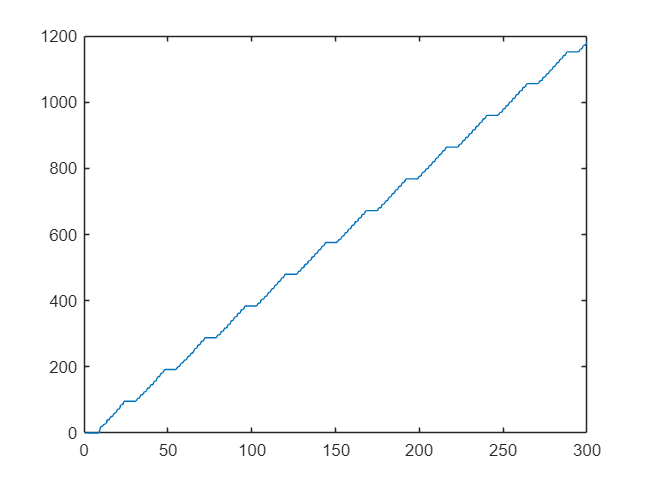


plot(1:300,returns_matrix(1:300,8));